# Time step comparison

dt = {};
dt{1} = load('/Users/chenjenchen/Mirror/cluster/pinst_compressible/build/example/NT64_IT50000/dt.txt');
dt{2} = load('/Users/chenjenchen/Mirror/cluster/pinst_compressible/build/example/NT128_IT200000/dt.txt');
dt{3} = load('/Users/chenjenchen/Mirror/cluster/pinst_compressible/build/example/NT256_IT800000/dt.txt');

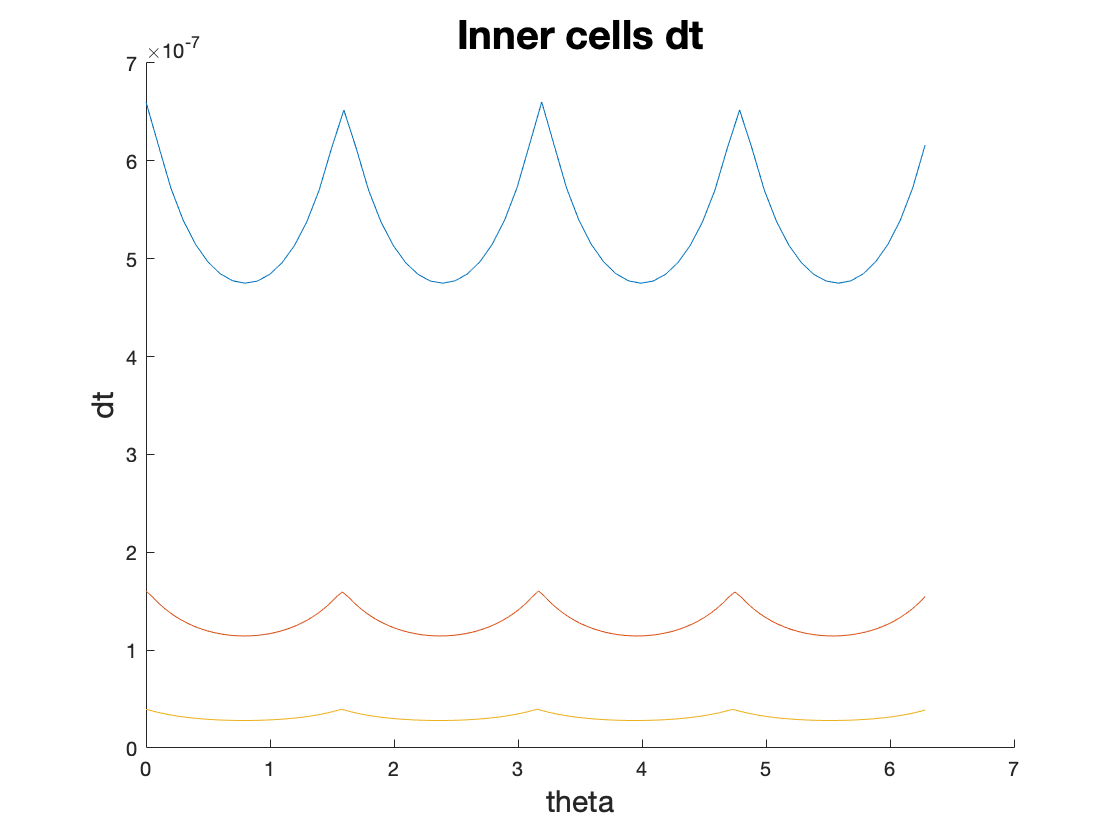

N = [64 128 256];
figure
hold on
for i = 1:length(N)
    x = linspace(0, 2*pi, N(i));
    plot(x,dt{i}(N(i)+1:2*N(i)))
end
title("Inner cells dt", "FontSize", 20)
xlabel("theta", "FontSize", 15)
ylabel("dt", "FontSize", 15)

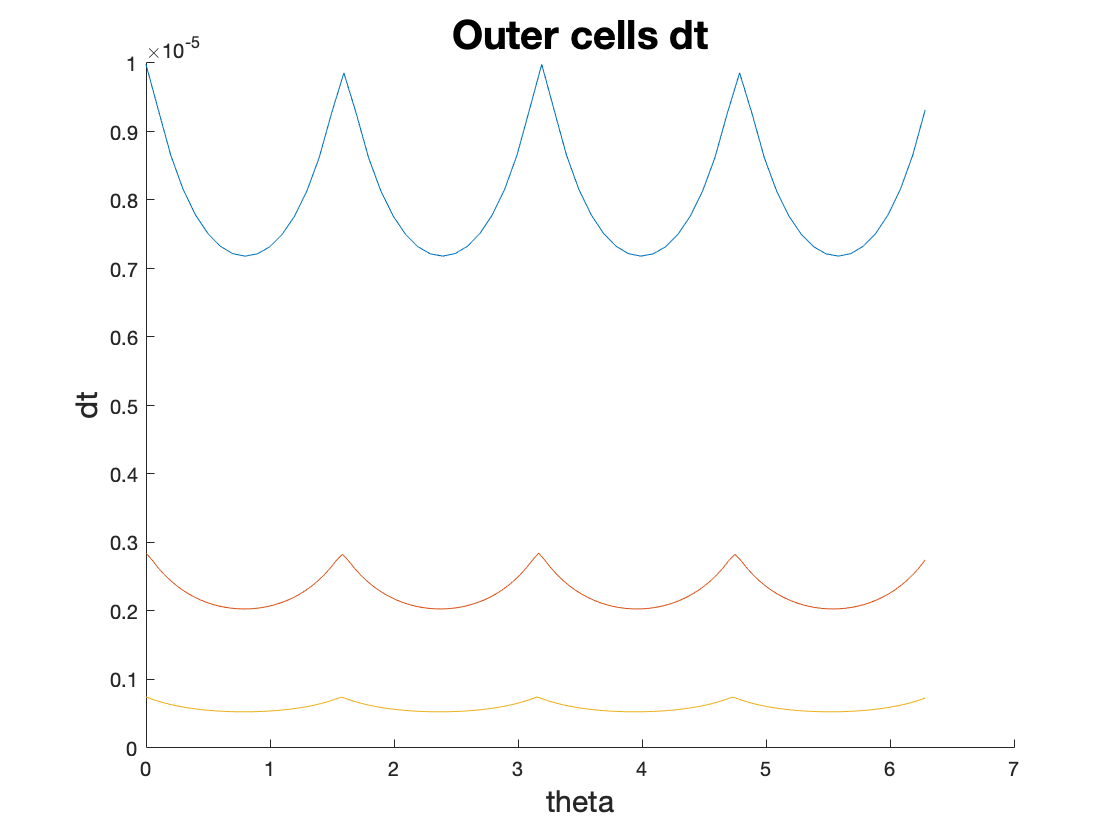

figure
hold on
for i = 1:length(N)
    x = linspace(0, 2*pi, N(i));
    plot(x,dt{i}(end-3*N(i)+1:end-2*N(i)))
end
title("Outer cells dt", "FontSize", 20)
xlabel("theta", "FontSize", 15)
ylabel("dt", "FontSize", 15)

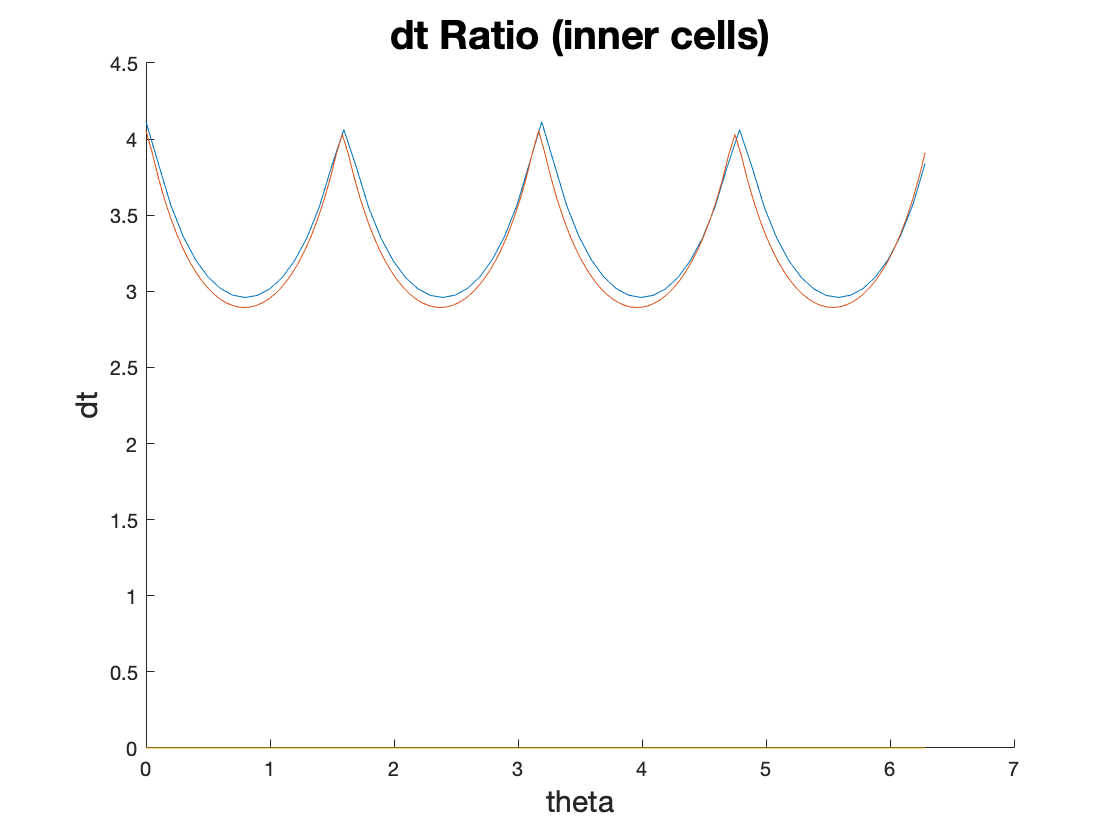

figure
hold on
for i = 1:length(N)-1
    x = linspace(0, 2*pi, N(i));
    plot(x,dt{i}(N(i)+1:2*N(i))/dt{i+1}(N(i+1)+1:2:2*N(i+1)))
end
title("dt Ratio (inner cells)", "FontSize", 20)
xlabel("theta", "FontSize", 15)
ylabel("dt", "FontSize", 15)

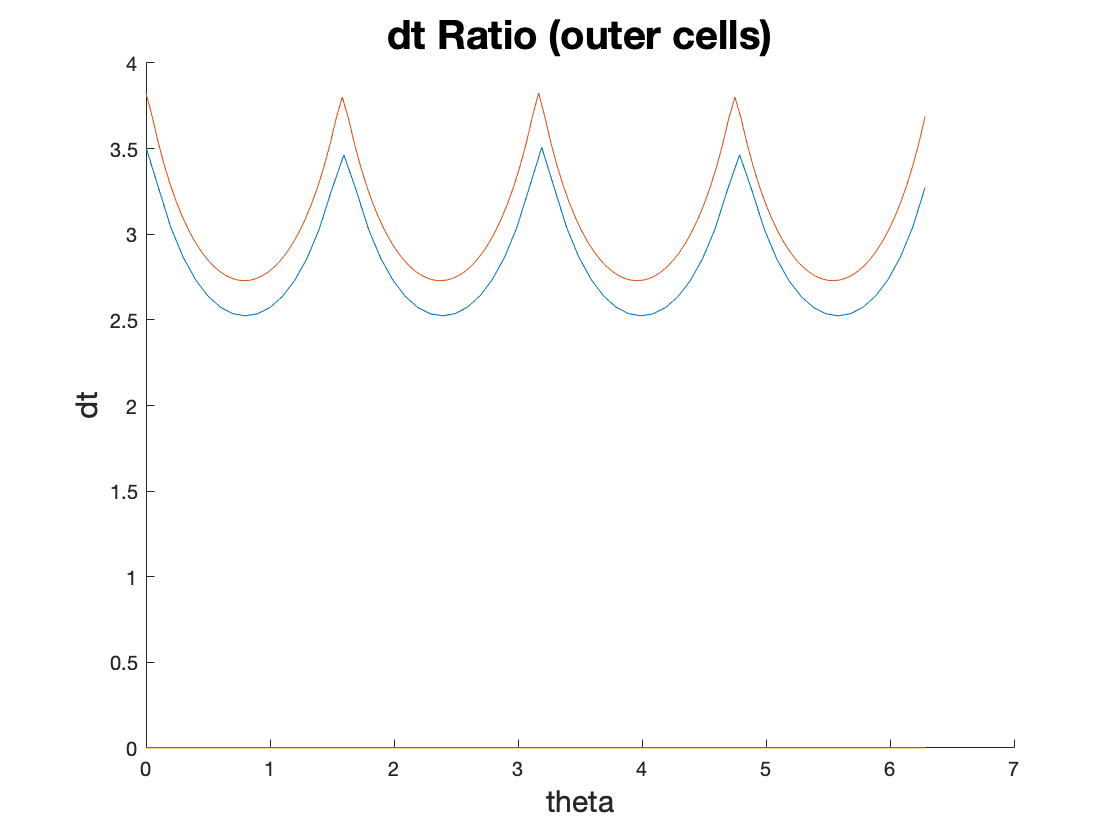

figure
hold on
for i = 1:length(N)-1
    x = linspace(0, 2*pi, N(i));
    plot(x,dt{i}(end-3*N(i)+1:end-2*N(i))/dt{i+1}(end-3*N(i+1)+1:2:end-2*N(i+1)))
end
title("dt Ratio (outer cells)", "FontSize", 20)
xlabel("theta", "FontSize", 15)
ylabel("dt", "FontSize", 15)